# Customize VTOL Configuration

This example guides the user on how to integrate their custom control and aircraft dynamics into the vertical takeoff and landing (VTOL) UAV template.

VTOL UAVs are capable of taking off and landing vertically with the ability to transition to fixed wing flight for the majority of mission. This VTOL UAV template models a tiltrotor where the front rotors can tilt to transition from hover to fixed wing flight.

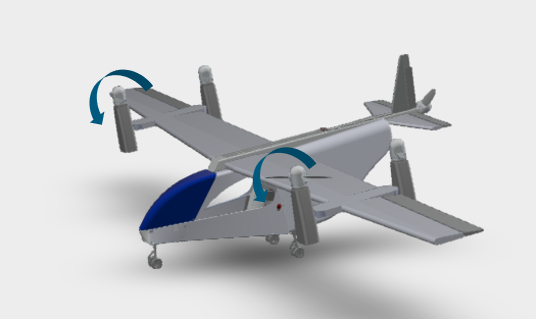

## Getting Started

Open the VTOL MATLAB project. 

prj = openProject('VTOLApp/VTOLRefApp.prj');

Click **Getting Started **button in the Project Shortcuts tab to set up the aircraft plant model and base controller. You can also set up the model and controller programmatically by using the `setupPlant` helper function.

setupPlant;

The `VTOLTiltrotor` Simulink® model contains these six subsystems that enable you to customize the VTOL UAV template:

- **Ground Control Station** – Contains a customized mission and sends the next state for the UAV mission to enable the VTOL UAV to execute a set of maneuvers.

- **Guidance Test Bench** – Allows switching between manual-control test bench and a guidance test bench. The guidance test bench consists of guidance logic that can be used to architect specific missions and test out control robustness.

- **Autopilot** – The controller for the VTOL aircraft.

- **Digital Twin** – The dynamics modeling of the VTOL including aerodynamics and propulsion.

- **Estimator** – Estimates the states of the VTOL aircraft based on sensor data and sends the state information to the ground control station and autopilot controller.

- **Visualization** – Visualize the UAV trajectory. 

Open the `VTOLTiltrotor` Simulink model.

open_system("VTOLTiltrotor")

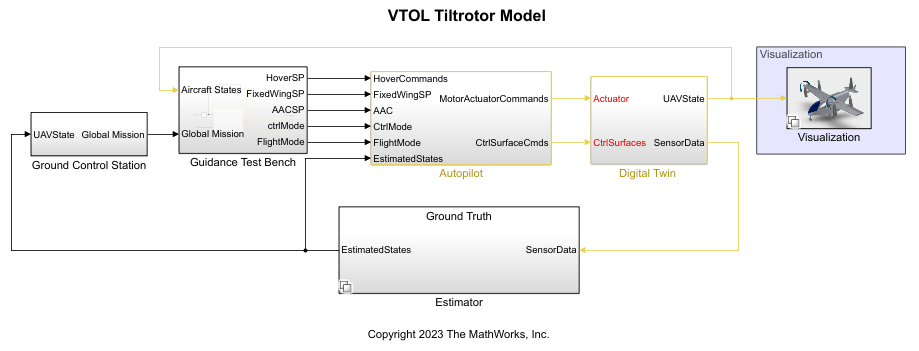

## Customize Aircraft Plant Model

To customize the control system of the aircraft plant model, you can modify the `Digital Twin` subsystem. By default the Digital Twin subsystem models a VTOL tiltrotor in the tiltrotors default configuration, but you change the settings to model a different VTOL UAV such as quadplane or tailsitter by modifying the dynamics. 

Open the `Digital Twin` subsystem.

open_system("VTOLTiltrotor/Digital Twin")

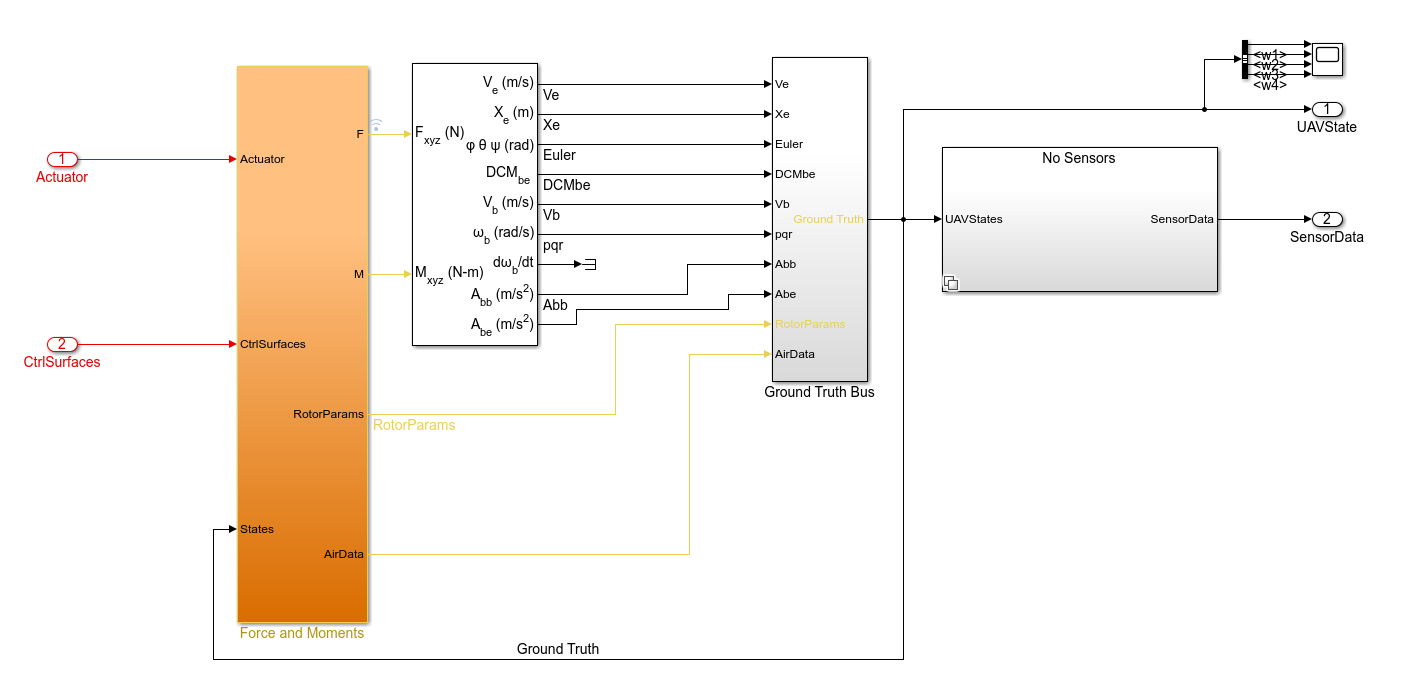

### VTOL Dynamics

The `Digital Twin` subsystem contains the `Forces and Moments` subsystem which enables you to customize the dynamics of the VTOL UAV plant model. 

Open the `Forces and Moments` subsystem.

open_system("VTOLTiltrotor/Digital Twin/Force and Moments")

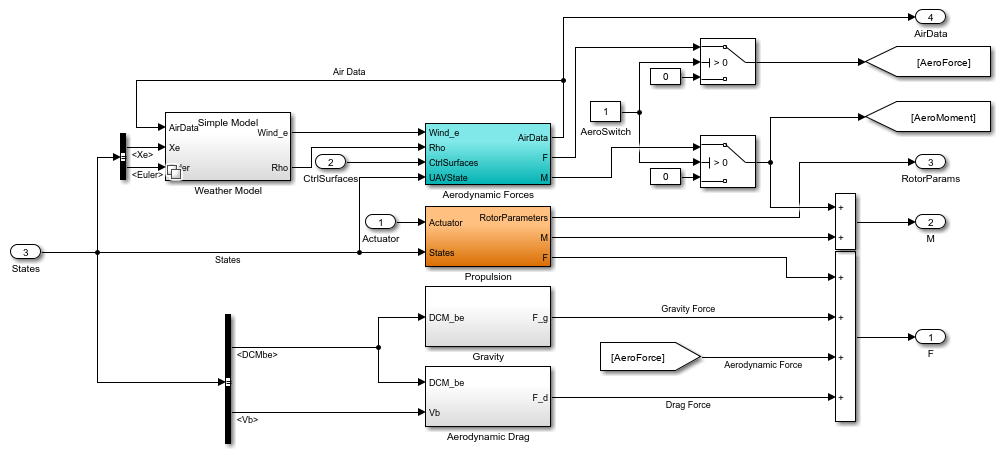

The `Forces and Moments` subsystem represents the kinematics of the VTOL aircraft using the [6DOF (Euler Angles)](docid:aeroblks_ug#f1-791506) block to determine body position, velocity, attitude, related values. 

### Wind Model

You can enable a wind model in the `Weather Model` subsystem*.* The subsystem takes in the fixed wing control surface commands and motor tilt commands and produces forces and moments. By default, the `Weather Model` subsystem does not model wind because it uses the `Simple Model` variant subsystem, but you can enable the `Weather Model` variant subsystem.

Open the `Weather Model` subsystem.

open_system("VTOLTiltrotor/Digital Twin/Force and Moments/Weather Model")

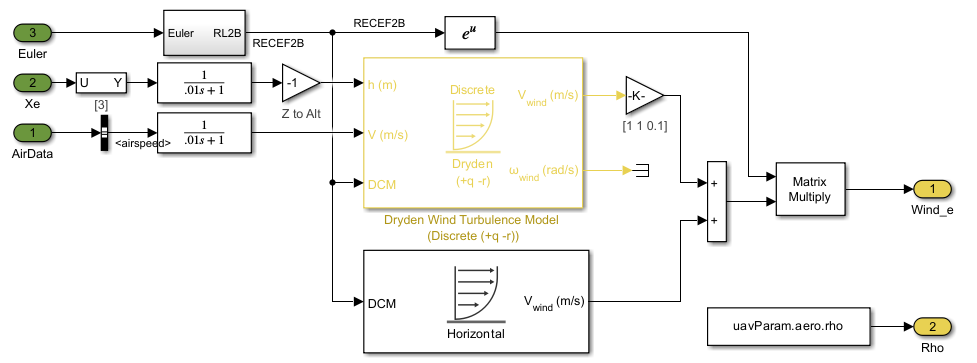

### Aerodynamics

Plug in the aerodynamic forces for your VTOL aircraft in the `Aerodynamic Forces` subsystem below in the lateral and longitudinal subsystems as highlighted below. You can also use the [Aerodynamic Forces and Moments](docid:aeroblks_ug#f1-1156057) block for modeling blocks to modeling aerodynamic forces.

Open the `Aerodynamic Forces` subsystem.

open_system("VTOLTiltrotor/Digital Twin/Force and Moments/Aerodynamic Forces")

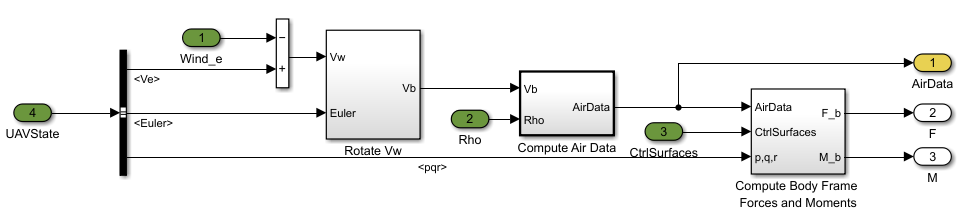

### Propulsion

You can customize the propulsion system using the `Propulsion` subsystem. By default, the subsystem configures the rotors to rotate dynamically for tiltrotor configurations. Each propulsion reference model in the subsystem represents a motor. So if you need to customize the propulsion system to use another configuration, such as a quadplane configuration, you must include a fifth rotor to the subsystem as another propulsion reference model and set the rotors to point up by setting the `RotorDirection` parameter of each rotor. You can set the fifth rotor using the same parameter to point forward or backwards accordingly.

Open the `Propulsion` subsystem.

open_system("VTOLTiltrotor/Digital Twin/Force and Moments/Propulsion")

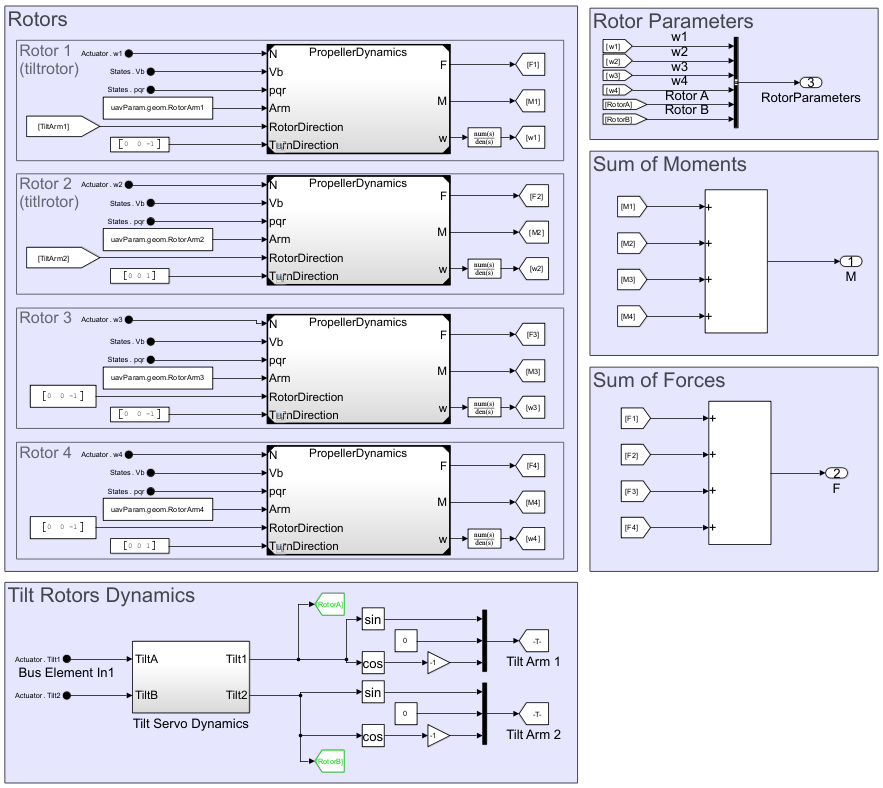

### Aerodynamics and Rotor Control Buses

Next you can update the bus interfaces into the aircraft within `defineDigitalTwinInterface`.

open('exampleHelperDefineDigitalTwinInterface.m')

You can customize the aerodynamic and rotor control buses to modify control surfaces and motors that are affecting vehicle dynamics. For example, if you set `w5` as the PWM input to a thrust motor and remove tilt inputs, you can define the interface for a quadplane rotor. 

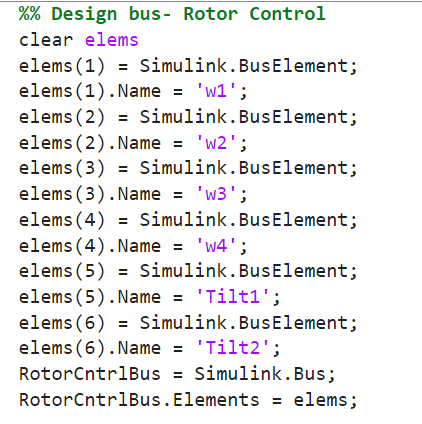

## Customize Control System

After modifying the plant dynamics in the previous section, the control system must be modified as well to support the VTOL in flight. By default, the autopilot controls a tiltrotor aircraft. To customize the autopilot control system first examine the layout of the controller in the Autopilot subsystem.

Open the `Autopilot` subsystem.

open_system("VTOLTiltrotor/Autopilot")

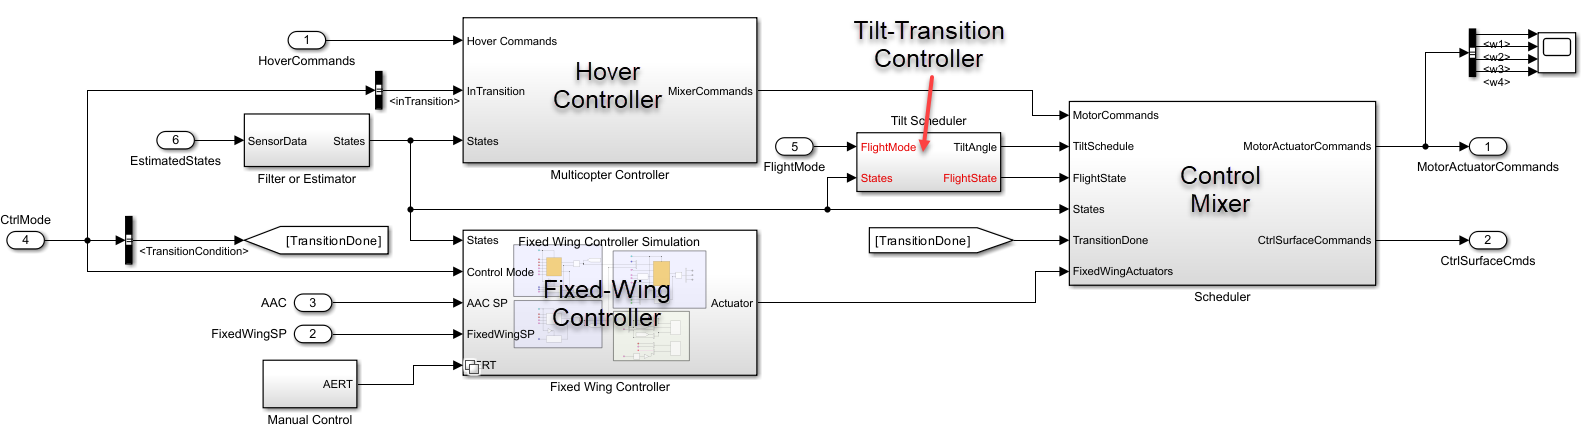

The control system blends between fixed wing and hover control. You can modify the tilt-transition controller in the **Tilt Scheduler** subsystem to control behavior of the tilt of front rotors while the VTOL aircraft is in either transition and back transition flight modes. You can use the **Scheduler** subsystem to customize the control mixer for the four different flight modes. For example, when the **Control Mixer** subsystem uses the multicopter mixing algorithm, it switches between the hover, transition, fixed-wing flight and back transition flight modes. While customizing the bus interface, ensure that the output bus highlighted below is consistent with the new definition. 

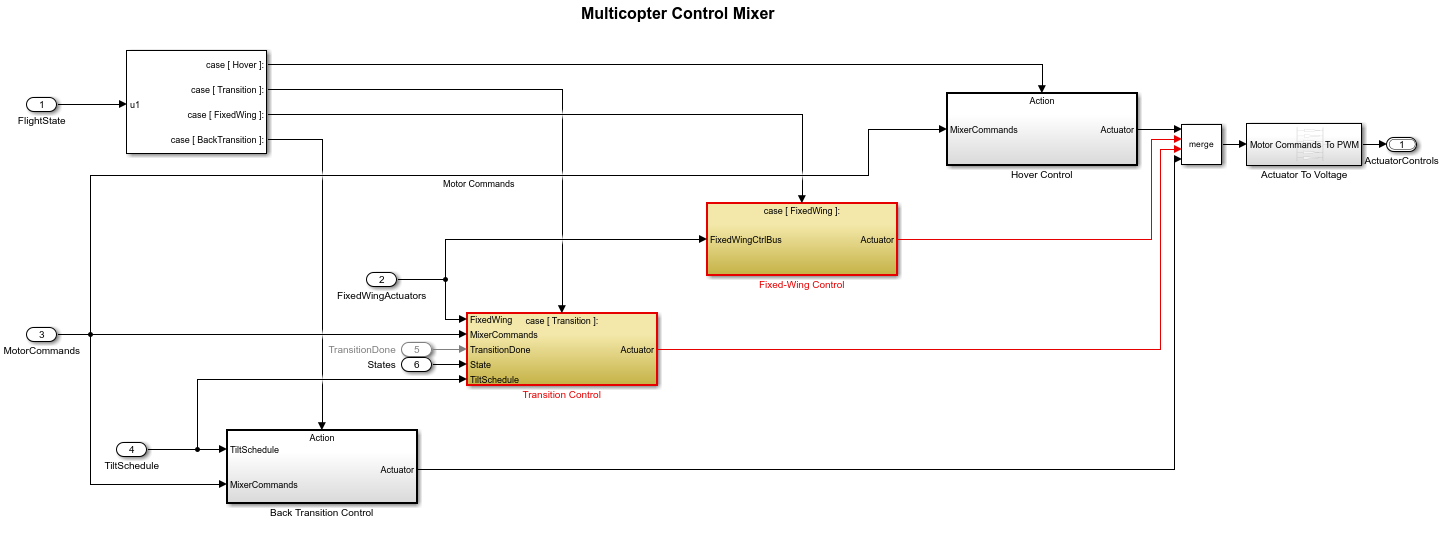

The `FlightState` input signal can represent one of four distinct flight modes of the VTOL UAV specified as an enumeration, `flightState`. You can modify the flightState variable by running one of setup helper functions, such as `setupHoverConfiguration`. These are the flight modes and their corresponding `flightState` values:

Hover — `0`

Transition — `1` 

Fixed Wing — `2`

Back Transition — `3`

You can modify the output bus interfaces for controller are fixed wing aerodynamic actuators and motor control in the `exampleHelperDefineDigitalTwinInterface` helper function*.*

## Customize Flight Mission

You can customize your flight mission using these modes based on the format that the [Path Manager](docid:uav_ref#mw_755010f7-0704-4c3d-9f31-3109be5b95b7) block uses. The VTOL flight mission uses the first four mission modes predefined by the Path Manager block. The fifth mission mode is return to launch but is unused for this mission. The sixth mission mode is a custom VTOL mission mode for transitioning back and forth between the hover and forward flight configurations. 

These are the integer values for the corresponding five mode types of the VTOL flight mission:

1 — Takeoff VTOL UAV

2 — Fly to a waypoint

3 — Orbit a point

4 — Land VTOL UAV

6 — Transition from hovering flight mode to fixed-wing flight mode when the VTOL aircraft is in hovering flight mode, or transition from fixed-wing flight mode to hovering flight mode when the VTOL aircraft is in fixed-wing flight mode.

You can only use mission modes 1 and 4 while the VTOL aircraft is in hovering flight mode. You can use mission modes 2, 3, and 6 for both fixed-wing flight mode and hover flight mode.

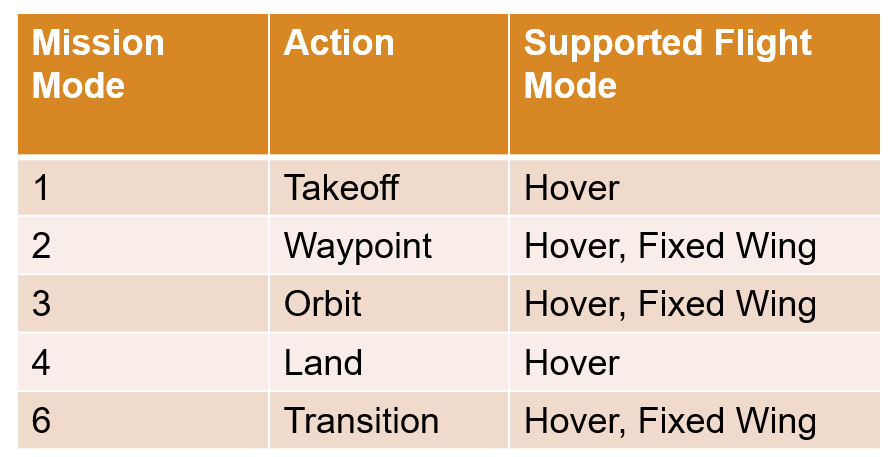

You can use the `exampleHelperTransitionMissionData` helper function to define a VTOL flight transition mission that commands the VTOL aircraft to:

- Takeoff from a starting position

- Hover to two waypoints

- Transition to fixed-wing flight mode

- Fly to a waypoint

- Orbit a waypoint

- Transition to hover flight mode

- Land at a end position

You can edit the helper file to modify the mission plan.

## Customize UAV Control in Mission Phases

The guidance mission test bench enables you to customize the control for each flight phase. 

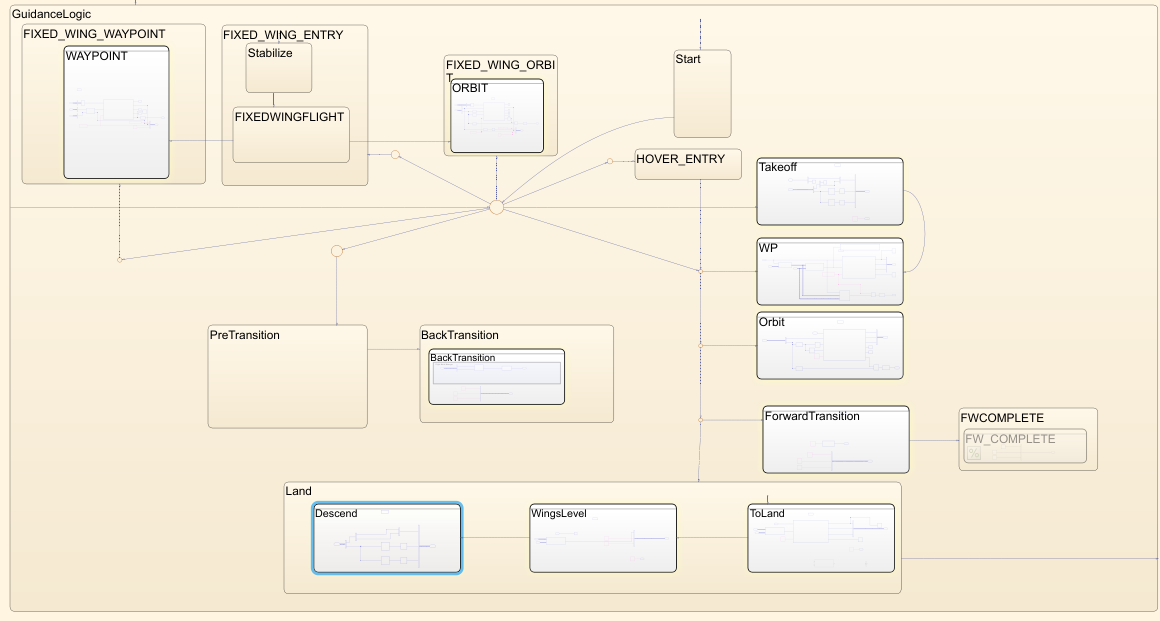

### Control Modes

Changing the control mode enables you to have granular control over the VTOL UAV within each flight mode. You can enable or disable any of these control parameters by setting the value of the parameter to `1` to enable controls and `0` to disable controls. To change the control mode, you must set **controlMode** within the Stateflow guidance above to see the effect on the flight path.

**lateralGuidance **— Allow course control in fixed wing mode. Disable during transition to minimize lateral motion.

**airspeedAltitude **— Allow airspeed and altitude control in fixed wing mode. Impacts setpoints of inner-loop attitude controller. This can be disabled to test performance of attitude controller.

**attitude **— Control attitude (roll-pitch-yaw) in fixed wing mode. Useful to stabilize aircraft in transition to fixed wing flight.

**inTransition **— Special flag that messages autopilot that aircraft is in transition. Affects tilt scheduler and controllers within autopilot.

**TransitionCondition **— Allows autopilot to determine when it is safe to fully switch to fixed wing control in transition.

Customize the control mode by adding more parameters by redefining the **controlMode** bus in `defineCtrlInterface`*.*

### Customizing Command Setpoints

You can also customize the setpoints at the input of autopilot. For example the AAC (Airspeed Altitude and Course bus is given below. 

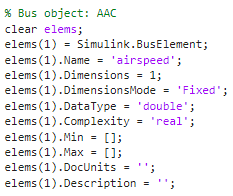

When you modify the bus interfaces, you must also set the corresponding values within the `Guidance Mode Selector` Stateflow chart. 

Open the `Guidance Mode Selector` Stateflow chart and set the bus definitions of the buses accordingly. 

open_system("VTOLTiltrotor/Guidance Test Bench/ControlType/Guidance Testbench/Guidance Logic/Guidance Stateflow/Guidance Mode Selector")

Select **Stateflow** **>** **Symbols Pane** **>** **Property Inspector** to examine bus interface.

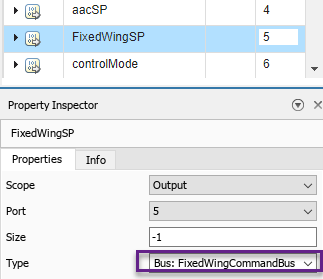

When customizing the inputs to autopilot, you must also redefine the defined inputs for manual control inside the `Manual Control` subsystem in `Guidance Testbench` when in manual mode.

## Summary

This example provides a walk through on how to customize and integrate custom modules for your application. Next, tune control design for a tiltrotor aircraft design.

**References**

[1] N., Pavan. (2020). Design of Tiltrotor VTOL and Development of Simulink Environment for Flight Simulations. 

[2] Mathur, Akshay & Atkins, Ella. (2021). Design, Modeling and Hybrid Control of a QuadPlane.

[3] Ducard, Guillaume Jacques Joseph and Minh-Duc Hua (2014). Modeling of an unmanned hybrid aerial vehicle.

*Copyright 2023 The MathWorks, Inc.*